clearvars;
load lombardgrid_paired/alignments_fixed.mat
load lombardgrid_paired/corpusCleaned.mat

savefolder = 'glo_STfilter';
savefile = 'result';

method = 6;

tic
globalModification(corpusCleaned, alignments, savefolder, savefile, method);

   100

   200

   300

   400

   500

   600

   700

   800

   900

        1000

        1100

        1200

        1300

        1400

        1500

        1600

        1700

        1800

        1900

        2000

        2100

        2200

        2300

        2400

        2500



toc

Elapsed time is 195.221481 seconds.


savefolder = 'glo_LPC';
savefile = 'result';

tic
globalModification(corpusCleaned, alignments, savefolder, savefile, method, 'lpc');

   100

   200

   300

   400

   500

   600

   700

   800

   900

        1000

        1100

        1200

        1300

        1400

        1500

        1600

        1700

        1800

        1900

        2000

        2100

        2200

        2300

        2400

        2500



toc

Elapsed time is 132.037318 seconds.


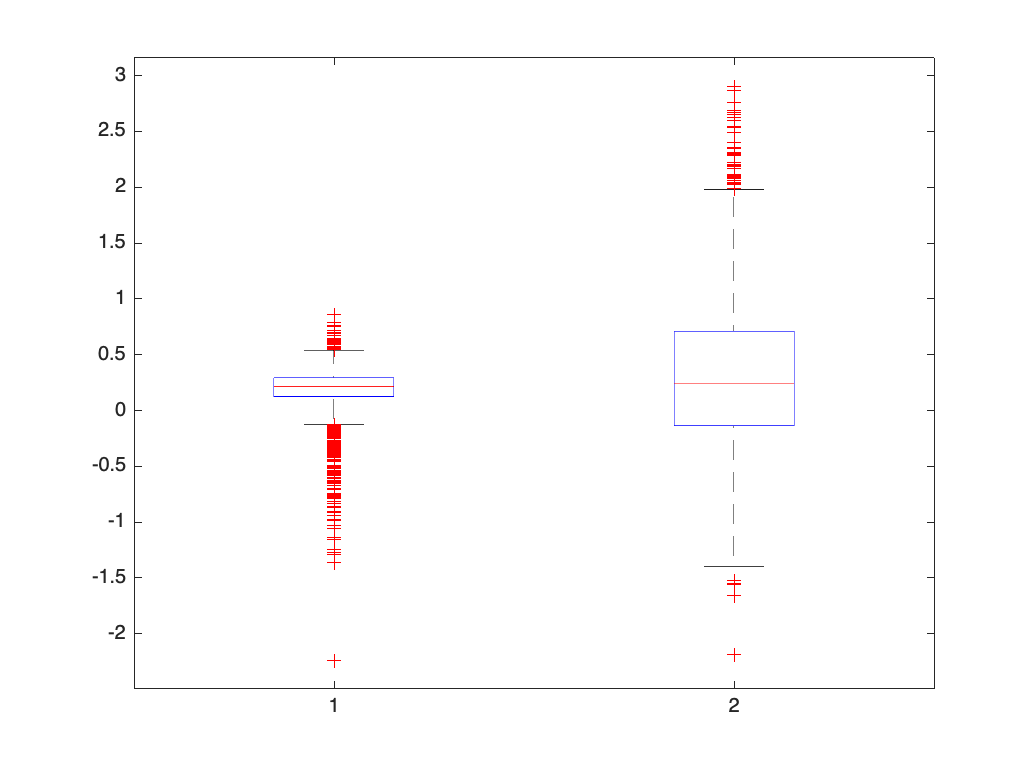

clearvars;
load glo_STfilter/result.mat
abserr_glo_ST = result.abserr_utter;

load glo_LPC/result.mat

abserr_glo_LPC = result.abserr_utter;

figure;
boxplot([abserr_glo_ST,abserr_glo_LPC])

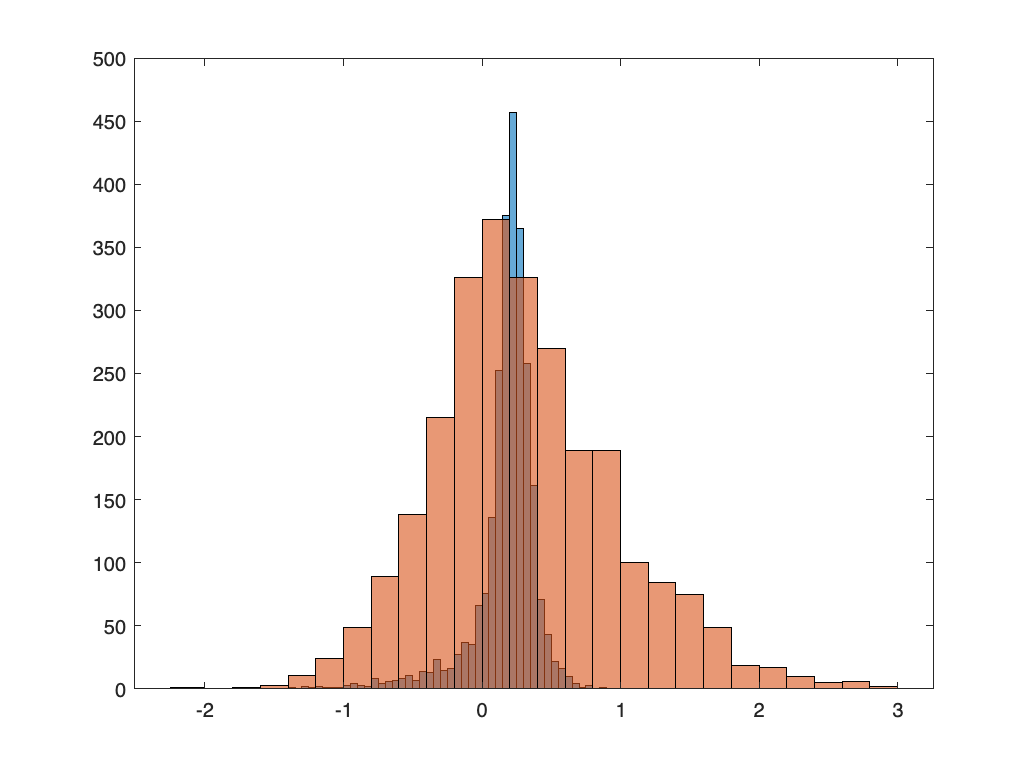


figure;
histogram(abserr_glo_ST)
hold on
histogram(abserr_glo_LPC)
hold off;


fprintf('mean:%.5f sigma:%.5f',mean(abserr_glo_ST),std(abserr_glo_ST))

mean:0.17341 sigma:0.23278


fprintf('mean:%.5f sigma:%.5f',mean(abserr_glo_LPC),std(abserr_glo_LPC))

mean:0.31038 sigma:0.67015